c= 0.18;                               %wind span for wing 1 in metres 
S= (0.18*0.087);                        %wing area for wing 1 in metres 
AR = S*(c^2);                            %wing 1 aspect ratio 
p = 1.225;                             %density of air kg/m3
v = 20;                                  % flow velocity 20 m/s
A0A = [-4 -2 0 2 4 6 8 10 12 14 16 18 20]

A0A =     -4    -2     0     2     4     6     8    10    12    14    16    18    20


AOAy = cosd(A0A);
AOAx = sind(A0A);

%L = (Ly.*AOAy)-(Dx.*AOAx)
% drag computation for wing one with flow 

AF_4 = mean ([ 0.073 0.073 0.073 0.071 0.071 0.072 0.071 0.071 0.071 0.071 0.077 0.079 0.079 0.079 0.08 0.082 0.08 0.08 0.08 0.079])

AF_4 = 0.0756

NF_4 = mean ([-0.072 -0.072 -0.072 -0.078 -0.078 -0.078 -0.081 -0.081 -0.083 -0.088 -0.088 -0.088 -0.092 -0.095 -0.095 -0.095 -0.095 -0.095 -0.095 -0.095])

NF_4 = -0.0858

D_4= ((AF_4*(cosd(-4)) ) + (NF_4*(sind(-4)) ));
L_4 = ((NF_4*(cosd(-4)) ) - (AF_4*(sind(-4) )));


AF_2 = mean([0.149 0.149 0.149 0.161 0.149 0.142 0.142 0.146 0.146 0.142 0.142 0.135 0.141 0.141 0.141 0.135 0.141 0.141 0.135 0.141]);
NF_2 = mean ([0.353 0.356 0.356 0.356 0.356 0.356 0.357 0.357 0.357 0.357 0.357 0.357 0.357 0.355 0.357 0.355 0.355 0.355 0.355 0.355]);
D_2= ((AF_2*(cosd(-2)) ) + (NF_2*(sind(-2)) ));
L_2= ((NF_2*(cosd(-2)) ) + (AF_2*(sind(-2) )));


AF0 = mean([0.208 0.208 0.208 0.208 0.208 0.208 0.214 0.213 0.2 0.215 0.214 0.214 0.215 0.221 0.221 0.221 0.221 0.221 0.229 0.221]);
NF0 = mean ([0.791 0.791 0.794 0.794 0.791 0.791 0.791 0.791 0.79 0.79 0.791 0.79 0.788 0.788 0.786 0.785 0.786 0.786 0.786 0.785]);
D0= ((AF0*(cosd(0)) ) + (NF0*(sind(0))));
L0= ((NF0*(cosd(0) )) + (AF0*(sind(0))));

AF2 = mean([0.279 0.28 0.279 0.279 0.279 0.278 0.279 0.279 0.277 0.268 0.268 0.268 0.268 0.277 0.277 0.268 0.269 0.269 0.269 0.269]);
NF2 = mean ([1.256 1.256 1.256 1.254 1.254 1.254 1.254 1.254 1.254 1.254 1.254 1.254 1.252 1.254 1.252 1.254 1.252 1.252 1.252 1.254]);
D2= ((AF2*(cosd(2)) ) + (NF2*(sind(2)) ));
L2= ((NF2*(cosd(2)) ) + (AF2*(sind(2)) ));

AF4 = mean([0.304 0.304 0.304 0.302 0.299 0.299 0.293 0.299 0.301 0.301 0.303 0.301 0.301 0.301 0.304 0.306 0.304 0.304 0.304 0.306]);
NF4 = mean ([1.667 1.668 1.668 1.667 1.668 1.668 1.668 1.674 1.674 1.675 1.68 1.68 1.675 1.674 1.68 1.682 1.68 1.68 1.682 1.68]);
D4= ((AF4*(cosd(4)) ) + (NF4*(sind(4)) ))

D4 = 0.4181

L4= ((NF4*(cosd(4)) ) + (AF4*(sind(4)) ))

L4 = 1.6915


AF6 = mean([0.323 0.318 0.321 0.319 0.321 0.316 0.316 0.316 0.316 0.316 0.316 0.309 0.306 0.309 0.301 0.31 0.31 0.31 0.311 0.311]);
NF6 = mean ([2.123 2.125 2.132 2.132 2.136 2.136 2.147 2.151 2.151 2.153 2.151 2.153 2.153 2.172 2.18 2.184 2.184 2.187 2.19 2.199]);
D6= ((AF6*(cosd(6)) ) + (NF6*(sind(6)) ));
L6= ((NF6*(cosd(6)) ) + (AF6*(sind(6)) ));


AF8 = mean([0.317 0.317 0.317 0.317 0.317 0.317 0.317 0.317 0.317 0.317 0.332 0.332 0.316 0.316 0.316 0.317 0.317 0.31 0.318 0.318]);
NF8 = mean ([2.407 2.405 2.405 2.402 2.402 2.402 2.402 2.402 2.402 2.402 2.419 2.423 2.423 2.423 2.426 2.448 2.449 2.453 2.466 2.466]);
D8= ((AF8*(cosd(8)) ) + (NF8*(sind(8)) ));
L8= ((NF8*(cosd(8)) ) + (AF8*(sind(8)) ));


dNF10 = mean ([3.06 3.064 3.07 3.07 3.073 3.073 3.073 3.088 3.105 3.105 3.088 3.088 3.088 3.078 3.077 3.073 3.073 3.073 3.077 3.077]);
D10= ((AF10*(cosd(10)) ) + (NF10*(sind(10) )));
L10= ((NF10*(cosd(10) )) + (AF10*(sind(10) )));

AF12 = mean([0.294 0.295 0.295 0.297 0.297 0.297 0.295 0.295 0.295 0.295 0.296 0.296 0.295 0.295 0.296 0.293 0.292 0.287 0.287 0.277]);
NF12 = mean ([3.49 3.491 3.487 3.484 3.484 3.484 3.484 3.487 3.487 3.491 3.498 3.498 3.498 3.498 3.498 3.498 3.485 3.485 3.485 3.481]);
D12= ((AF12*(cosd(12)) ) + (NF12*(sind(12)) ));
L12= ((NF10*(cosd(10)) ) + (AF10*(sind(10) )));


AF14 = mean([0.273 0.273 0.273 0.273 0.273 0.249 0.25 0.251 0.252 0.252 0.249 0.249 0.249 0.25 0.25 0.236 0.236 0.236 0.236 0.243]);
NF14 = mean ([3.778 3.778 3.782 3.782 3.795 3.795 3.809 3.843 3.857 3.862 3.862 3.864 3.87 3.881 3.89 3.89 3.881 3.892 3.892 3.892]);
D14= ((AF14*(cosd(14)) ) + (NF14*(sind(14)) ));
L14= ((NF14*(cosd(14) )) + (AF14*(sind(14)) ));

AF16 = mean([0.208 0.209 0.209 0.202 0.208 0.204 0.209 0.204 0.204 0.204 0.2 0.2 0.2 0.205 0.205 0.204 0.204 0.205 0.205 0.205]);
NF16 = mean ([4.139 4.158 4.161 4.17 4.191 4.213 4.225 4.225 4.225 4.233 4.233 4.233 4.233 4.233 4.233 4.233 4.233 4.236 4.219 4.213]);
D16= ((AF16*(cosd(16) )) + (NF16*(sind(16)) ));
L16= ((NF16*(cosd(16)) ) + (AF16*(sind(16)) ));


AF18 = mean([0.174 0.173 0.173 0.174 0.174 0.175 0.175 0.167 0.167 0.15 0.168 0.143 0.169 0.145 0.145 0.17 0.145 0.145 0.145 0.145]);
NF18 = mean ([4.246 4.246 4.246 4.263 4.265 4.287 4.291 4.316 4.329 4.337 4.36 4.361 4.384 4.396 4.404 4.404 4.415 4.421 4.421 4.421]);
D18= ((AF18*(cosd(18)) ) + (NF18*(sind(18)) ));
L18= ((NF18*(cos(18)) ) + (AF18*(sind(18)) ));


AF20 = mean([0.103 0.103 0.103 0.101 0.104 0.104 0.104 0.105 0.105 0.105 0.106 0.106 0.106 0.106 0.089 0.089 0.088 0.088 0.09 0.088]);
NF20 = mean ([4.604 4.604 4.607 4.61 4.624 4.63 4.631 4.651 4.657 4.657 4.672 4.682 4.682 4.686 4.702 4.702 4.702 4.713 4.713 4.713]);
D20= ((AF20*(cosd(20)) ) + (NF20*(sind(20)) ));
L20= ((NF20*(cosd(20)) ) + (AF20*(sind(20) )));


AF1 = [AF_4 AF_2 AF0 AF2 AF4 AF6 AF8 AF10 AF12 AF14 AF16 AF18 AF20];
NF1 = [NF_4 NF_2 NF0 NF2 NF4 NF6 NF8 NF10 NF12 NF14 NF16 NF18 NF20];

Cd = (2* (AF1))./(p*(v.^2)*S)                      % profile drag 

Cd =     0.0197    0.0374    0.0559    0.0714    0.0787    0.0818    0.0829    0.0786    0.0765    0.0659    0.0534    0.0420    0.0260


Cl = (2* (NF1))./(p*(v.^2)*S)                      % lift coefficient from normal force computation

Cl =    -0.0224    0.0928    0.2057    0.3268    0.4364    0.5622    0.6311    0.8024    0.9095    1.0021    1.0978    1.1313    1.2151



Cdi =  ((Cl.^2) / (pi * AR ) )                        %induced drag 

Cdi =     0.3137    5.3998   26.5477   66.9968  119.5000  198.2795  249.8693  403.9413  518.9929  629.9903  756.0736  802.9846  926.3196


CD = Cd + Cdi                                        % total drag coefficient 

CD =     0.3334    5.4372   26.6036   67.0682  119.5787  198.3613  249.9522  404.0199  519.0694  630.0562  756.1270  803.0266  926.3456



%CALCULATING COEFFICIENT OF PITCHING MOMENT 

A = 0.028  ;                 %DISTANCE FROM THE LOAD CELL
C =  0     ;                   %DISTANCE FROM LOAD CELL END TO REFERENCE POINT 
m_4 = mean([-2.766 -2.766 -2.766 -2.766 -2.766 -2.76 -2.76 -2.761 -2.765 -2.761 -2.765 -2.794 -2.807 -2.821 -2.83 -2.843 -2.843 -2.843 -2.876 -2.876]);                       %measured moment in Ncm 
M_4 = (m_4 * 0.01 )   ;              %measured moment in Nm 

m_2 = mean([-1.557 -1.555 -1.536 -1.536 -1.536 -1.521 -1.516 -1.516 -1.496 -1.496 -1.496 -1.496 -1.496 -1.477 -1.477 -1.496 -1.496 -1.496 -1.496 -1.477]);
M_2 = (m_2 * 0.01 ) ;

m0 = mean([-0.007 -0.009 -0.007 -0.007 -0.012 -0.012 -0.02 -0.03 -0.034 -0.034 -0.059 -0.059 -0.059 -0.059 -0.061 -0.063 -0.061 -0.061 -0.063 -0.08]);
M0 = (m0 * 0.01 ) ;

m2 = mean([1.278 1.295 1.278 1.258 1.258 1.255 1.251 1.258 1.258 1.25 1.25 1.25 1.249 1.249 1.249 1.249 1.241 1.241 1.238 1.235]);
M2 = (m2 * 0.01 ) ;

m4 = mean([2.607 2.609 2.617 2.609 2.609 2.609 2.609 2.609 2.609 2.617 2.617 2.617 2.617 2.598 2.598 2.617 2.584 2.584 2.628 2.628]);
M4 = (m4 * 0.01 ) ;

m6 = mean([3.948 3.952 3.97 3.97 3.979 3.985 4.005 4.007 4.007 4.007 4.029 4.028 4.028 4.048 4.048 4.048 4.048 4.048 4.055 4.056]);
M6 = (m6 * 0.01 ) ;

m8 = mean([4.903 4.916 4.903 4.899 4.903 4.905 4.905 4.905 4.916 4.916 4.916 4.936 4.936 4.936 4.951 4.958 4.951 4.958 5.005 5.005]);
M8 = (m8 * 0.01 ) ;

m10 = mean([6.631 6.636 6.636 6.636 6.636 6.639 6.649 6.698 6.696 6.696 6.696 6.698 6.696 6.686 6.649 6.649 6.644 6.644 6.649 6.649]);
M10 = (m10 * 0.01 ) ;

m12 = mean([7.791 7.791 7.79 7.783 7.783 7.783 7.783 7.79 7.806 7.807 7.834 7.834 7.834 7.834 7.834 7.82 7.807 7.807 7.807 7.759]);
M12 = (m12 * 0.01 ) ;

m14 = mean([8.587 8.587 8.587 8.613 8.62 8.624 8.661 8.693 8.79 8.807 8.819 8.823 8.859 8.859 8.86 8.9 8.9 8.926 8.926 8.927]);
M14 = (m14 * 0.01 ) ;

m16 = mean([9.644 9.666 9.668 9.749 9.757 9.832 9.835 9.835 9.835 9.839 9.839 9.839 9.861 9.861 9.861 9.839 9.832 9.831 9.817 9.817]);
M16 = (m16 * 0.01 ) ;

m18 = mean([10.117 10.147 10.147 10.15 10.155 10.17 10.242 10.336 10.356 10.386 10.391 10.42 10.434 10.479 10.5 10.528 10.543 10.543 10.543 10.543]);
M18 = (m18 * 0.01 ); 

m20 = mean([11.153 11.153 11.152 11.157 11.152 11.156 11.202 11.207 11.207 11.226 11.285 11.295 11.295 11.331 11.347 11.347 11.331 11.347 11.353 11.353]);
M20 = (m20 * 0.01 ) ;


M = [M_4 M_2 M0 M2 M4 M6 M8 M10 M12 M14 M16 M18 M20]  % COMPUTED PITCHING MOMENT AT ALL AOA

M =    -0.0280   -0.0151   -0.0004    0.0125    0.0261    0.0401    0.0493    0.0666    0.0780    0.0877    0.0980    0.1036    0.1125



Mref = (M - (A + 0 ) * NF1 )

Mref =    -0.0256   -0.0251   -0.0225   -0.0226   -0.0208   -0.0203   -0.0185   -0.0196   -0.0197   -0.0200   -0.0199   -0.0180   -0.0180




CM = (2*Mref )/ (p * v^2 * S*c)

CM =    -0.0370   -0.0363   -0.0326   -0.0327   -0.0301   -0.0293   -0.0268   -0.0284   -0.0285   -0.0289   -0.0288   -0.0260   -0.0261




%plot graph 
P1 = linspace(min(A0A),max(A0A),13)

P1 =     -4    -2     0     2     4     6     8    10    12    14    16    18    20


z1 = interp1(A0A, Cl,'spline')

z1 =    -6.0447   -5.8144   -5.5886   -5.3464   -5.1271   -4.8756   -4.7378   -4.3952   -4.1809   -3.9958   -3.8044   -3.7373   -3.5697


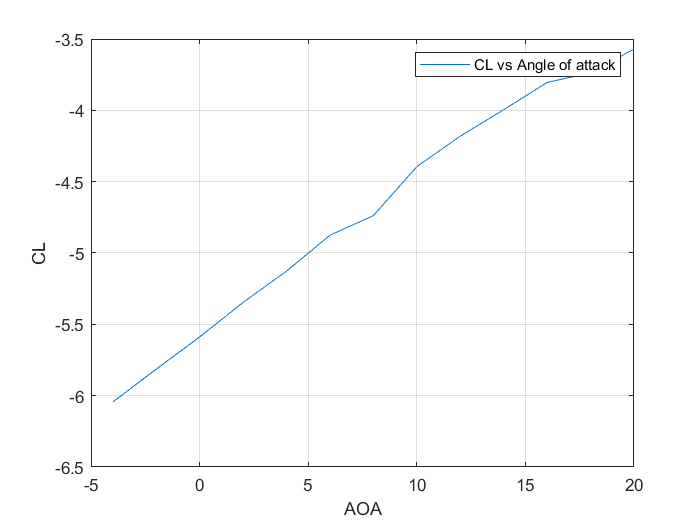

plot (P1, z1)
%plot (A0A, Cl)
xlabel ('AOA')
ylabel ('CL')
legend ('CL vs Angle of attack' )
grid on 

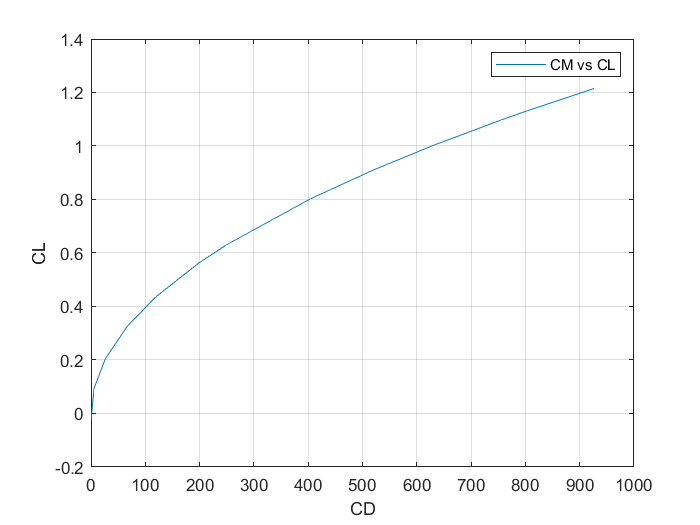


plot (CD, Cl)
xlabel ('CD')
ylabel ('CL')
legend ('CM vs CL' )
grid on 

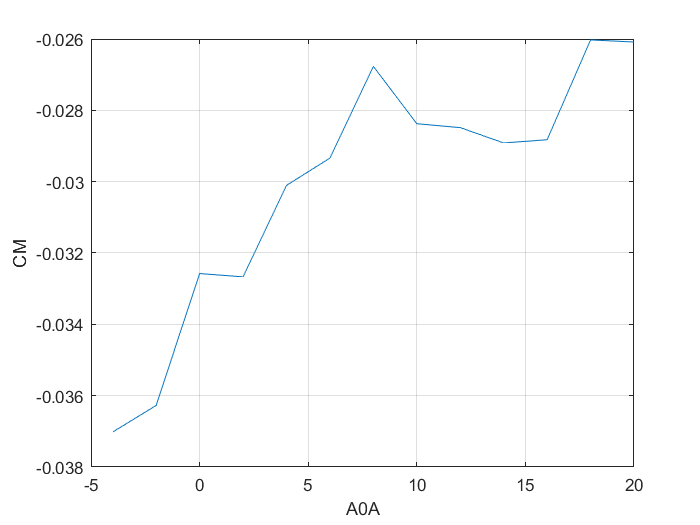




plot (A0A, CM)
xlabel ('A0A')
ylabel ('CM')
grid on 



%   Boundary corrections 

K = 0.90                    %body shape factor for 3.D wing

K = 0.9000

C = 0.10675             %wind tunnel area in metres

C = 0.1068

S = 0.01566           %wing area in metres 

S = 0.0157


%solid blockage 
dsb = (K/(C^(3/2)))

dsb = 25.8042




%wake blockage with flow seperation